# **双根传输线对应的磁场分布**

**        两条彼此平行、载有方向相反的恒定电流的无穷长直导线产生的磁场是一种很典型的磁场分布。我们应用磁矢势来分析双根传输线产生的磁场．由于两导线无穷长，故其产生的磁场必是一个平行平面磁场，在每一个与载流导线垂直的平面内，磁场分布相同。取定直角坐标，并令导线与 z 轴平行，y 轴过这两条直导线的连线的中点。如图1所示。**

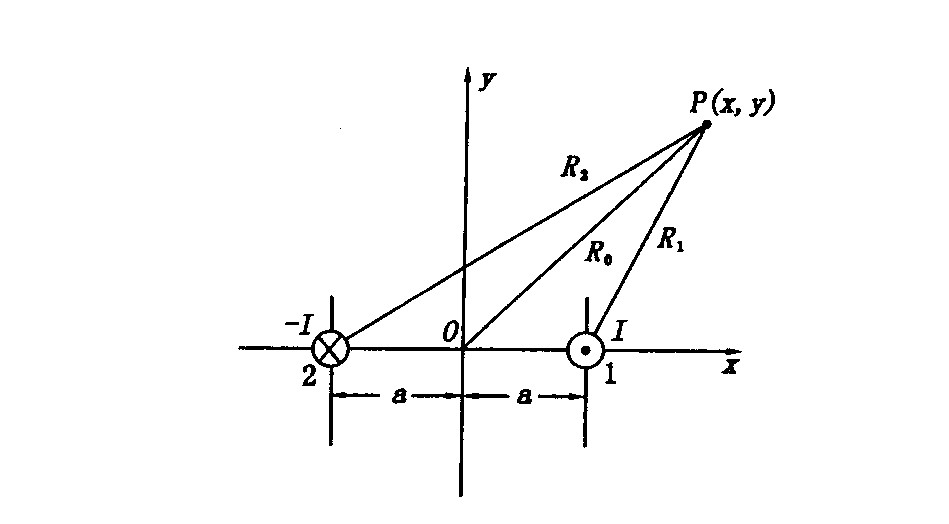

图1 双线输电线剖面图[1] 

**        为简单起见，取场点P落在xy平面内，则在P点，导线1、2中的电流各自激发的磁矢势分别为：**


$$\vec{A_1 } {=-\left(\frac{\mu_0 I}{2\pi }\ln \frac{R_1 }{R_0 }\right)\;\vec{e_z } }_{\;}$$



$$\vec{A_2 } {=\left(\frac{\mu_0 I}{2\pi }\ln \frac{R_2 }{R_0 }\right)\;\vec{e_z } }_{\;}$$


**        我们已选择了z轴上的某一点为矢势零点,**$R_0$**是P点到z轴的垂直距离,**$R_1 =\sqrt{{\left(x-a\right)}^2 +y^2 }$**,**$R_2 =\sqrt{{\left(x+a\right)}^2 +y^2 }$**。P点的磁矢势为： **


$$\vec{A} {=\vec{A_1 } +\vec{A_2 } =\left(\frac{\mu_0 I}{2\pi }\ln \frac{R_2 }{R_1 }\right)\;\vec{e_z } =\left(\frac{\mu_0 I}{4\pi }\ln \frac{{\left(x+a\right)}^2 +y^2 }{{\left(x-a\right)}^2 +y^2 }\right)\;\vec{e_z } }_{\;}$$


**        磁感应强度**$\vec{B} =\nabla \times \vec{A}$**，**$\vec{B}$**的分量为：**


$$\begin{array}{l}
\vec{B_x } =\frac{\partial \vec{A} }{\partial y}=\frac{\mu_0 I}{2\pi }\left(\frac{y}{R_2^2 }-\frac{y}{R_1^2 }\right)\\
\vec{B_y } =-\frac{\partial \vec{A} }{\partial x}=-\frac{\mu_0 I}{2\pi }\left(\frac{x+a}{R_2^2 }-\frac{x-a}{R_1^2 }\right)\\
\vec{B_z } =0
\end{array}$$


- **定义相关常数及网格划分**

MU0=4*pi*1e-7;                        %真空中的磁导率
I0=1;                 %自定义电流大小
R=10;                  %自定义两根传输线之间的距离
a=R/2;                                %一根传输线距原点的距离
C=MU0/(2*pi)*I0;                      %归并常数
Nx=41;Ny=41;Nz=41;                    %自定义观测点网格数
x=linspace(-R,R,Nx);                  %观测点范围
y=linspace(-R,R,Ny);
z=linspace(-R,R,Nz);
[X,Y]=meshgrid(x,y);

- **计算各网格点上的B(x,y)值**

R1=(X-a).^2+Y.^2;               %场点与右边传输线距离的平方
R2=(X+a).^2+Y.^2;               %场点与左边传输线距离的平方
Bx=C*(Y./R2-Y./R1);             %磁感应强度的x分量
By=C*((X+a)./R2-(X-a)./R1);     %磁感应强度的y分量
Bz=0;                           %磁感应强度的z分量

- **绘制矢量场图**

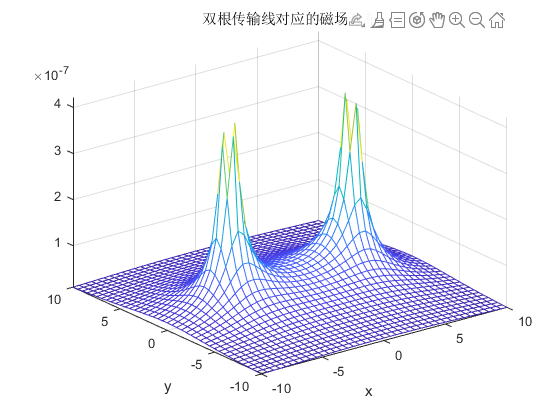

B=sqrt(Bx.^2+By.^2+Bz.^2);       %总磁感应强度大小
meshc(x,y,B)  
title('双根传输线对应的磁场分布');
xlabel('x');
ylabel('y');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **绘制二维等高线**

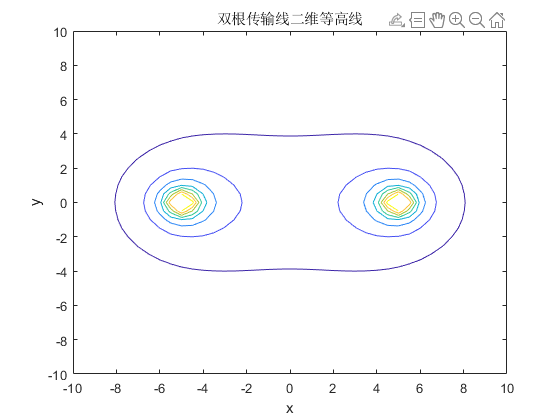

figure;
contour(X,Y,B);            
title('双根传输线二维等高线');
xlabel('x');
ylabel('y');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **绘制30条三维等高线**

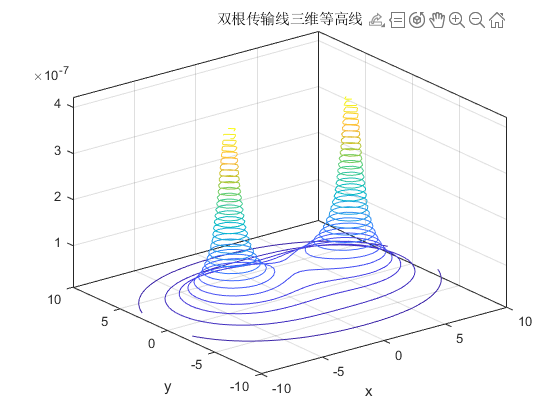

figure;
contour3(X,Y,B,30);            
title('双根传输线三维等高线');
xlabel('x');
ylabel('y');
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        从MATLAB展示的以上图中，我们可以清楚地看到双根传输线磁场的特点，其产生的磁场是一个平行平面磁场，在每一个与载流导线垂直的平面内，磁场分布相同。**

- **参考文献：**

**                [1] 殷岳才.两条平行的无穷长载流直导线产生的磁场[J].沈阳师范学院学报(自然科学版),2002(02):95-98.**